## explore the metabolic pathways of Energy generation

### ATP contributing(production) rxns

% from genericMetaboContribution
% predict Flux Split
transportRxns = {'ATPtm','ATPtn','ATPtx','ATP1ter','ATP2ter','EX_atp[e]','DNDPt13m'...
    ,'DNDPt2m','DNDPt31m','DNDPt56m','DNDPt32m','DNDPt57m','DNDPt20m','DNDPt44m'...
    ,'DNDPt19m','DNDPt43m','r1116'};

ATPprod = {'ATPS4mi','PGK','PYK','SUCOASm'}';

met2test = {'atp[c]','atp[m]','atp[n]','atp[r]','atp[x]', ...
    'atp[l]', 'atp[i]', 'atp[e]', 'atp[p]'};
%Metabotools tutorial II
obj = 'ATPM'; %previously 'DM_atp_c_';
clear ResultsAllCellLines

%Identify the highest contributing reactions to ATP production and consumption:
dir = 1; % ATP production(contribution) 

%FVA=1;% use fastFVA changing lb and ub
FVA=0; % no difference to use or not use FVA (optimize space within the current bound space)
method='eFBA';
IdentifyATPcontribution

Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.1.31 (Build date: 2024-5-6 11:08:30)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3653            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4578            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2999
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries  

%Identify the highest contributing reactions to ATP production and consumption:
dir = 0; % ATP consumption

%FVA=1;% use fastFVA changing lb and ub
FVA=0;
method='eFBA';
IdentifyATPcontribution

Input model is feasible according to optimizeCbModel.
Using existing internal net flux bounds without modification.

MOSEK Version 10.1.31 (Build date: 2024-5-6 11:08:30)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Linux/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : LO (linear optimization problem)
  Constraints            : 3653            
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 4578            
  Matrix variables       : 0               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Eliminator started.
Freed constraints in eliminator : 2999
Eliminator terminated.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 10
Eliminator terminated.
Eliminator - tries  

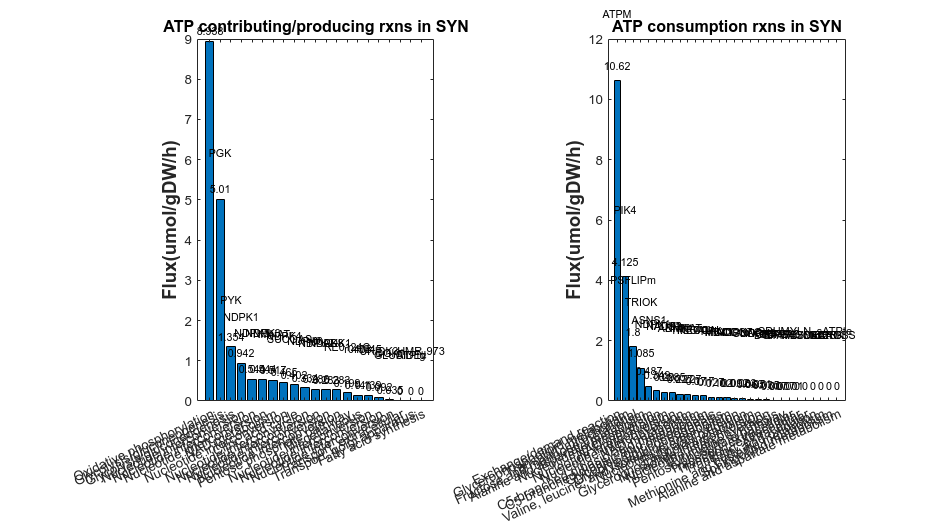

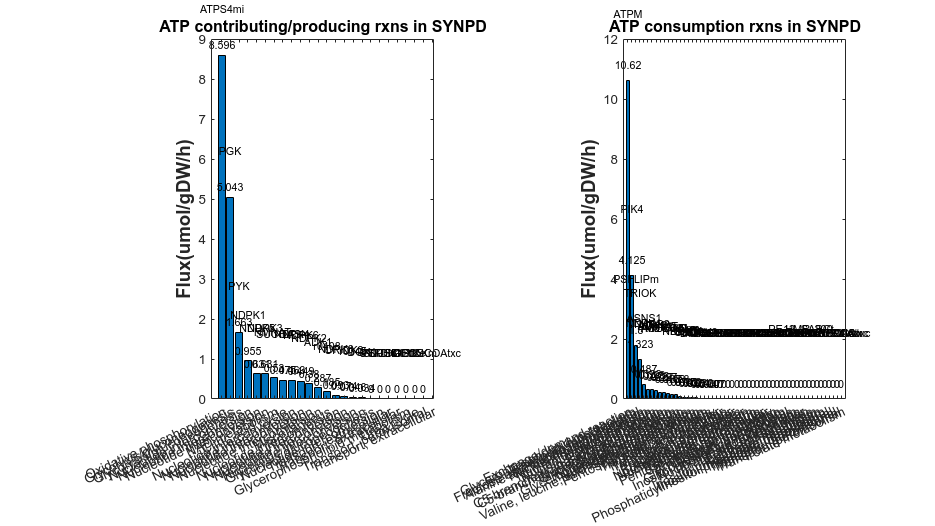

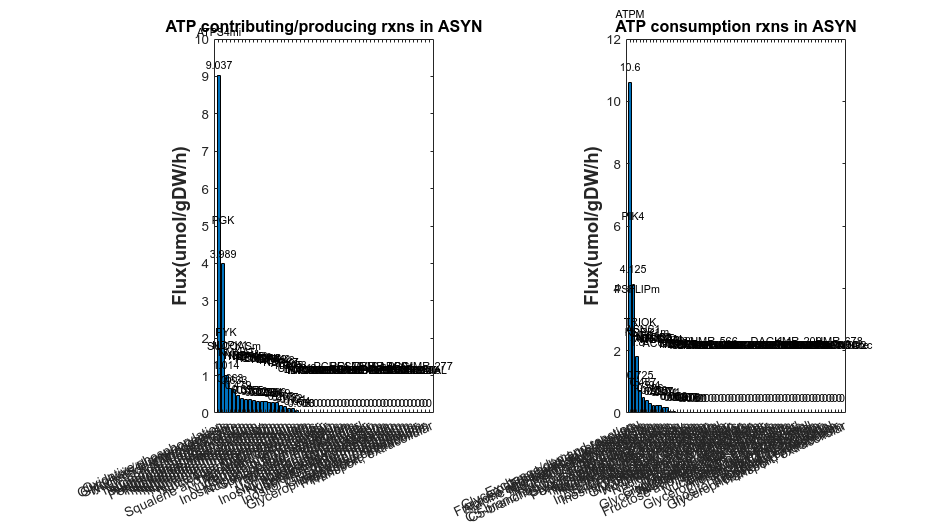

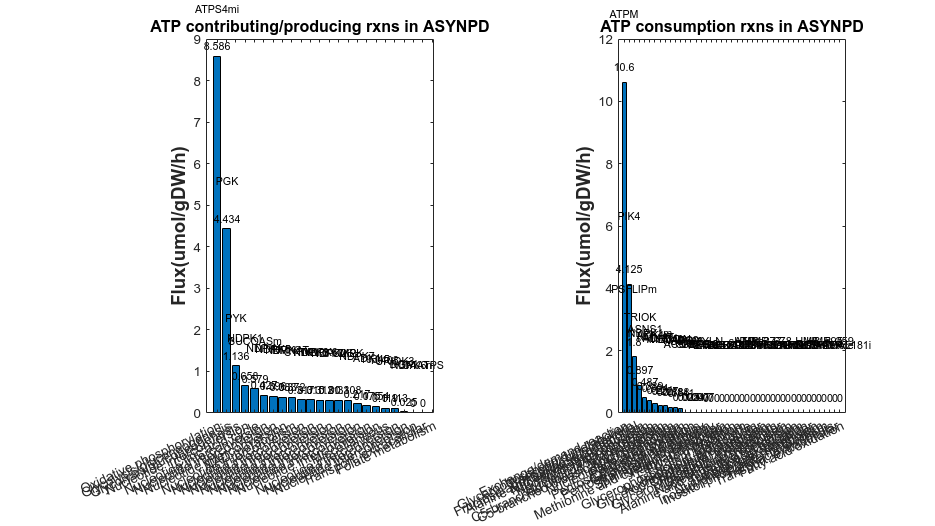

% plot the flux value/proportion for atp production and consumption rxns
plotATPproductionandConsumption(Allmodels,ATPproduction,ATPconsumption) % most of the consumption is from ATPM

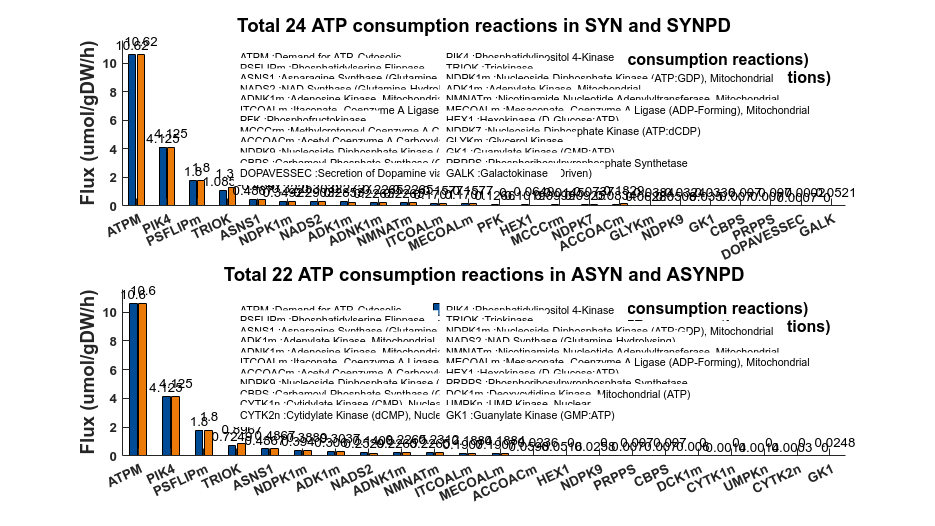

% compare the all rxns for contribution/production
% plot all ATP contribution/production rxns
plotATPRxns(ATPconsumption, Allmodels,0) % 0=consumption; 1=contribution

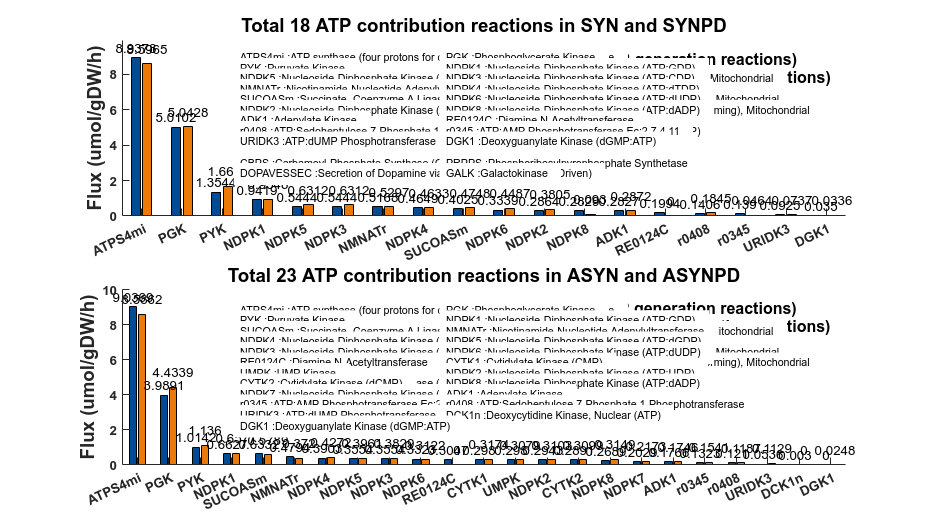

plotATPRxns(ATPproduction, Allmodels,1) % 0=consumption; 1=contribution